# Prueba hibrida: dinamica V8 y seguimiento Pure Pursuit

Integra sin modificar las ecuaciones de la planta V8 y los controladores de la practica 4. Circuito nuevo de conos con rectas y curvas interiores y exteriores. Dos referencias de velocidad: 6 y 14 m/s. Los resultados distinguen vuelta completa y salida del carril. Fuentes originales: CuatroruedasV8_bloqueo_ruedas.mlx y P4_seguimiento_trayectoria_ALUMNO.mlx.

% Fuente: CuatroruedasV8_bloqueo_ruedas.mlx | SHA256: 5502b64c9336f6cbfcc394f0d39e986e2266b3d37636013bea30260a9f8ffa1c
% Fuente: P4_seguimiento_trayectoria_ALUMNO.mlx | SHA256: 58965f692cf38b8a1928c7ddcf16276dcb8aee7fd3a043acc123b057dd832679
%% Dinamica V8 y seguimiento Pure Pursuit de la practica 4
% Archivo independiente. Las funciones fisicas de V8 y los controladores
% de P4 se incorporan sin modificar sus ecuaciones. No lee ni escribe los
% originales, ni necesita los scripts externos de Ensayos.
% La geometria, el integrador del ensayo y sus graficas son nuevos.
% No incorpora ESC, ABS, TCS ni planificacion de velocidad en curva.

%% Parametros originales de V8
p = struct(); 

p.m    = 230;      % masa [kg]                              
p.g    = 9.81;     % gravedad [m/s^2]
p.rho  = 1.225;    % densidad del aire [kg/m^3]
p.Cd   = 1.0;      % coef. aerodinámico                       
p.Af   = 1.1;      % área frontal [m^2]                        
p.fr  = 0.022;    % coef. de resistencia a la rodadura       
p.Fx_drive_max = 2500;   % fuerza motriz máxima [N]           
p.Fx_brake_max = 5000;   % fuerza de frenado máxima [N]       
p.theta = 0;      % inclinación de la calzada [rad]

% Define aquí los parámetros necesarios para describir la dinámica lateral
% del vehículo
p.ld = 0.765; % [m] distancia del CG al eje delantero en x
p.lt = 0.765; % [m] distancia del CG al eje trasero en x
p.lyd = 0.600; % [m] distancia del CG a las ruedas del eje delantero en y
p.lyt = 0.600; % [m] distancia del CG a las ruedas del eje trasero en y
p.hcg = 0.230; % [m] altura del centro de gravedad
% Coordenadas de cada rueda respecto al CG
% Orden: DI, DD, TI, TD
p.xw = [p.ld,p.ld,-p.lt,-p.lt];
p.L = p.ld+p.lt; 
p.yw = [p.lyd, -p.lyd, p.lyt, -p.lyt];
p.td = p.lyd + p.lyt;
p.tt = p.td; 
p.Iz = 130; % [kg m^2] inercia de guiñada
p.Cad = 35000; % [N/rad] rigidez deriva delantera
p.Cat = 50000; % [N/rad] rigidez deriva trasero --> vehículo subvirador! 
p.Caw = [p.Cad/2, p.Cad/2, p.Cat/2, p.Cat/2];
p.nCa = 0.8; 
p.mu_t = 1.5; % rozamiento neumático trasero
p.mu_d = 0.95*p.mu_t; % rozamiento neumático delantero
p.muw = [p.mu_d, p.mu_d, p.mu_t, p.mu_t];
% Perdida de adherencia lateral por exceso de traccion
p.Kslip = 3; % Intensidad de perdida lateral en ruedas traseras
% Dinamica temporal de perdida y recuperacion lateral
p.tau_slip_loss = 0.03; % Tiempo de perdida [s]
p.tau_slip_rec  = 0.50; % Tiempo de recuperacion [s]
% Perdida de adherencia por exceso de demanda de frenado.
% Valores iniciales de ensayo, pendientes de calibracion.
% Dos modos de frenado: normal y bloqueo aproximado.
% Parametros ilustrativos; pendientes de calibracion experimental.
p.brake_slide_ratio = 0.68; % mu_min / mu_base (limite a alta velocidad)
p.v_brake_slide = 15;      % Escala de velocidad [m/s]
p.brake_lock_on = 1.02;    % Entrada: demanda / capacidad nominal
p.brake_lock_off = 0.90;   % Salida con histeresis
p.tau_brake_loss = 0.03;   % Transicion al objetivo en bloqueo [s]
p.tau_brake_rec = 0.10;    % Recuperacion al aliviar parcialmente [s]
p.tau_brake_release = 0.01;% Recuperacion rapida al soltar: 95% en 30 ms

% Reparto de fuerzas
p.Fzd0 = p.m*p.g*p.lt/p.L; % [N] Reparto de fuerzas inicial eje delantero
p.Fzt0 = p.m*p.g*p.ld/p.L; % [N] Reparto de fuerzas inicial eje trasero
p.Fzw0 = [p.Fzd0/2, p.Fzd0/2, p.Fzt0/2, p.Fzt0/2]; % [N] Reparto de fuerzas inicial rueda por rueda
p.drive_w = [0, 0, 0.5, 0.5]; % Reparto de tracción longitudinal en aceleración
p.brake_w = [0.3, 0.3, 0.2, 0.2]; % Reparto de tracción longitudinal en frenada
p.kRoll = 0.5; % fraccion del momento de balanceo soportada delante (Cambiar haciendo modelo de suspensión)



%% Controladores de P4 y configuracion del ensayo
p.Kp_v=800; p.Ki_v=200;
p.Ld0=2.0; p.kLd=0.3; p.delta_max=0.5;
p.dt=0.002;
ensayo.ancho=3.0;             % Distancia entre bordes [m]
ensayo.pasoTrayectoria=0.25;  % Resolucion geometrica maxima [m]
ensayo.pasoConos=3.0;         % Separacion aproximada de conos [m]
ensayo.velocidades=[6 10];    % Moderado y exigente [m/s]
ensayo.errorAbandono=10;      % Detener si se pierde ampliamente la pista [m]

%% Circuito con rectas, curvas exteriores e interiores
pista=generarCircuitoHibrido(ensayo);
centro=pista.centro; cono_izq=pista.conoIzq; cono_der=pista.conoDer;
fprintf('\nCircuito: %.2f m; ancho %.1f m; %d rectas y %d curvas.\n', pista.longitud,ensayo.ancho,height(pista.curvas),height(pista.curvas));


Circuito: 272.24 m; ancho 3.0 m; 8 rectas y 8 curvas.


disp(pista.curvas);

    Curva    Radio_m      Sentido         Tipo       CentroX_m    CentroY_m
    _____    _______    ___________    __________    _________    _________

      1        10       "izquierda"    "exterior"       10           10    
      2        14       "izquierda"    "exterior"       56           14    
      3        10       "izquierda"    "exterior"       60           40    
      4         6       "izquierda"    "exterior"       51           44    
      5         6       "derecha"      "interior"       39           34    
      6         7       "derecha"      "interior"       32           35    
      7         9       "izquierda"    "exterior"       16           51    
      8        12       "izquierda"    "exterior"       12           48    




%% Ejecucion independiente de los dos niveles de velocidad
resultados=cell(numel(ensayo.velocidades),1);
for caso=1:numel(ensayo.velocidades)
    pCaso=p; pCaso.v_set=ensayo.velocidades(caso);
    resultados{caso}=simularHibrido(pCaso,pista,ensayo);
end

Caso 6.0 m/s: vuelta completada, t=44.16 s, max |e|=1.016 m.
Caso 10.0 m/s: vuelta completada, t=26.33 s, max |e|=1.123 m.


histNominal=resultados{1};
histExigente=resultados{2};

%% Resumen y graficas
resumen=resumirHibrido(resultados,ensayo);
disp(resumen);

    Vref_ms    VueltaCompleta    TiempoSimulado_s    ErrorMedio_m    ErrorRMS_m    ErrorMax_m    TiempoFueraCarril_pct    Saturacion_pct    Bloqueo_pct
    _______    ______________    ________________    ____________    __________    __________    _____________________    ______________    ___________

       6           true               44.164           0.28941        0.40829        1.0158                0                  1.6846             0     
      10           true               26.334           0.37638        0.52114        1.1233                0                  12.227             0     



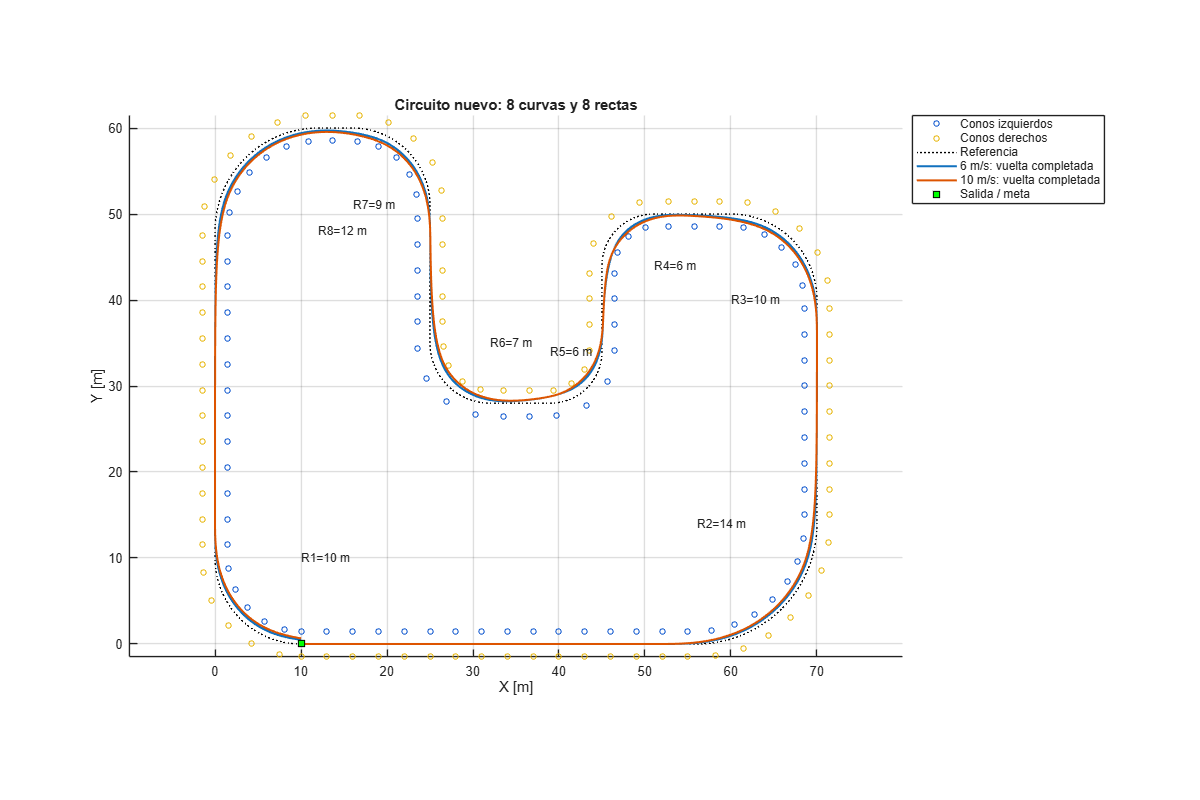

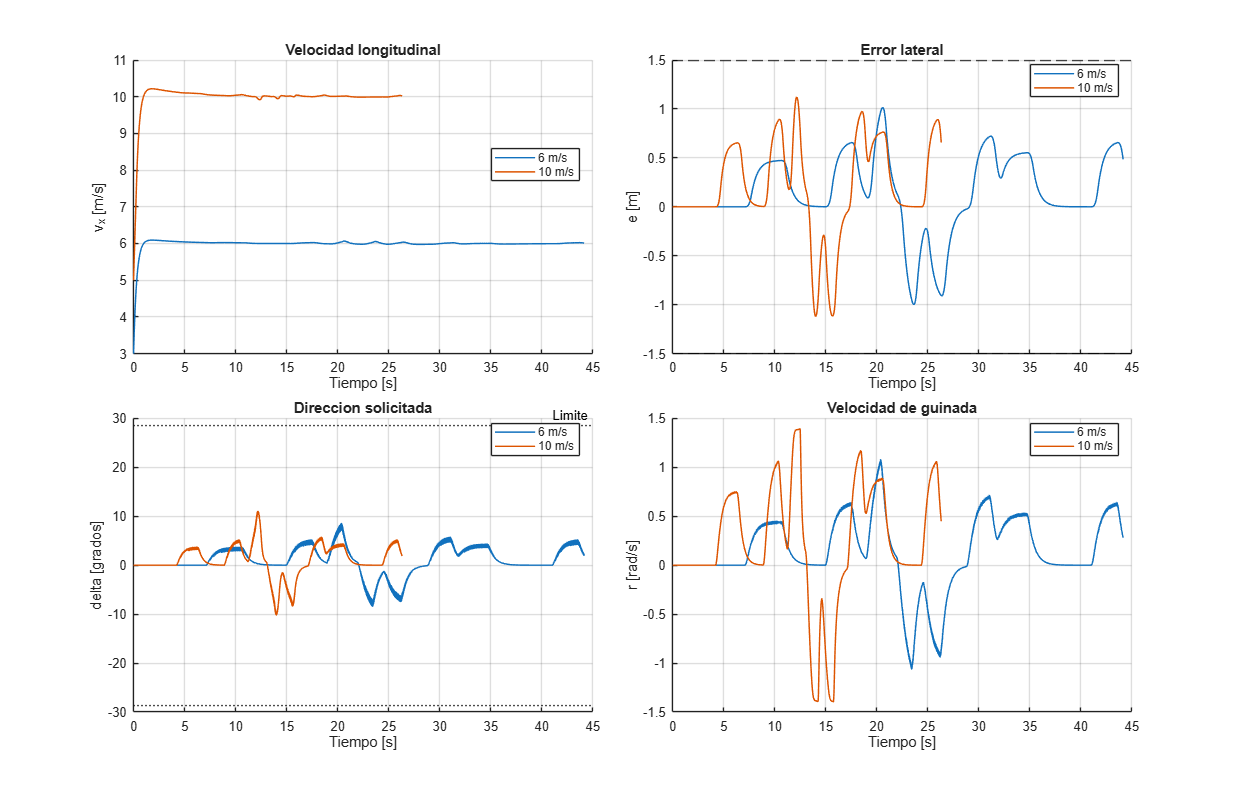

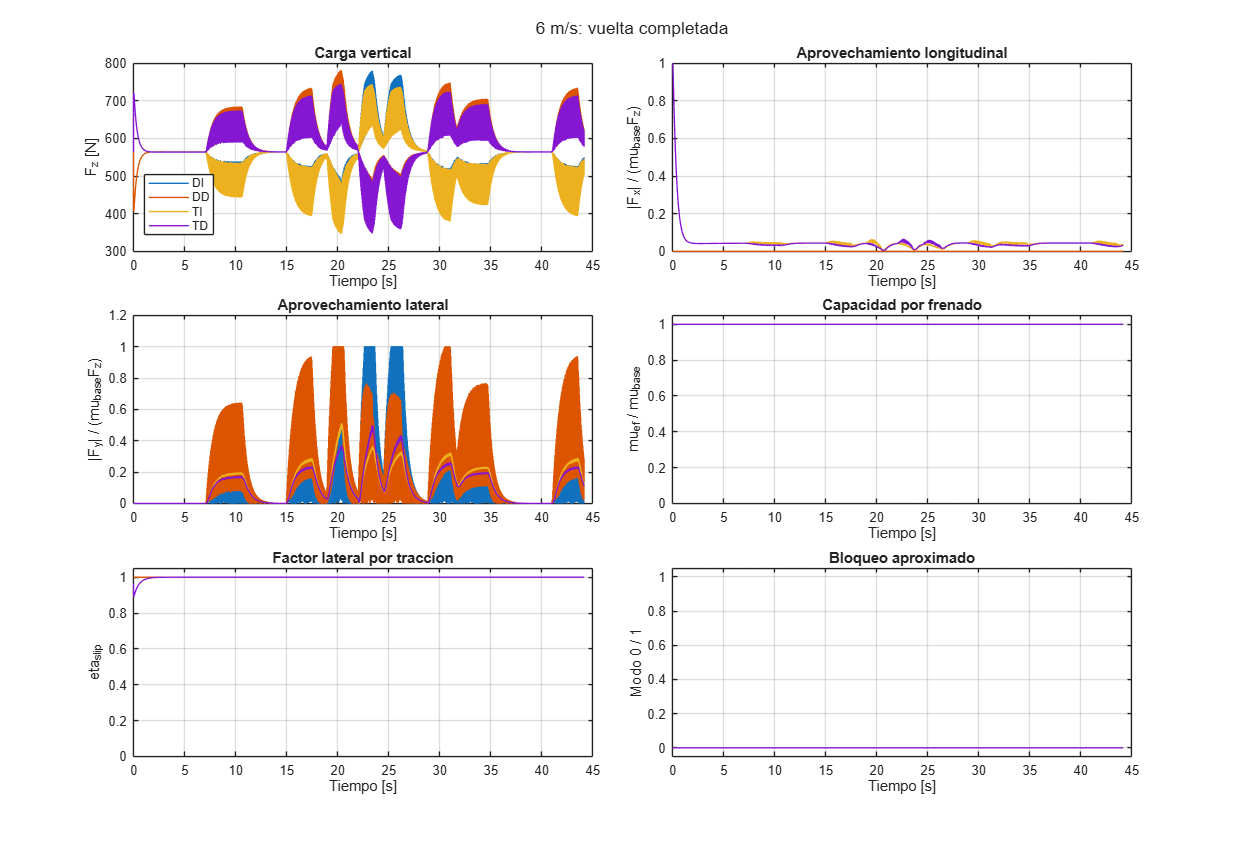

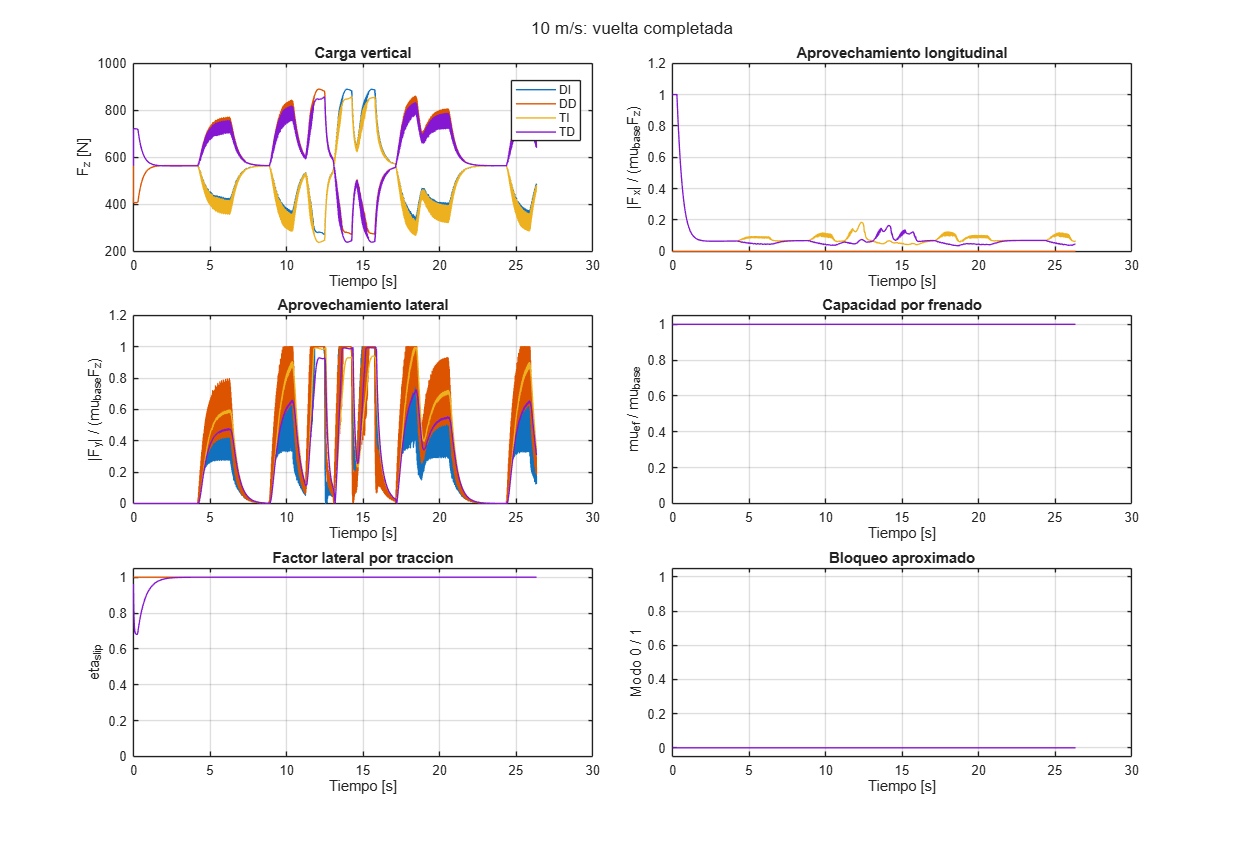

mostrarHibrido(resultados,pista,ensayo,p);

fprintf(['\nInterpretacion: completar la vuelta no garantiza permanecer en el carril.\n' ...
    'El criterio de carril corresponde al centro de gravedad, sin envolvente de carroceria.\n' ...
    'Las curvas de bloqueo representan la aproximacion fenomenologica de V8.\n']);


Interpretacion: completar la vuelta no garantiza permanecer en el carril.
El criterio de carril corresponde al centro de gravedad, sin envolvente de carroceria.
Las curvas de bloqueo representan la aproximacion fenomenologica de V8.



%% Funciones fisicas y controladores copiados de los originales
function [z_next, tele] = pasoDinamico(z, u, p, dt)
    % Estado completo (20x1), orden por rueda DI, DD, TI, TD:
    % 1:6   X, Y, psi, vx, vy, r (movimiento)
    % 7:8   ax, ay del paso anterior (transferencia cuasiestatica)
    % 9:12  eta_slip (memoria de adherencia lateral)
    % 13:16 eta_brake (memoria de capacidad de frenado)
    % 17:20 bloqueo_w (modo discreto, 0 o 1)
    if ~isvector(z) || numel(z) ~= 20
        error('pasoDinamico:EstadoInvalido', 'El estado dinamico debe tener 20 componentes; inicializa su memoria.');
    end
    z = z(:);
    ax_prev = z(7);
    ay_prev = z(8);
    eta_prev = z(9:12).';
    eta_brake_prev = z(13:16).';
    bloqueo_prev = logical(z(17:20).');
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    vy = z(5);
    r = z(6);
    L = p.ld + p.lt;
    xw = p.xw;
    yw = p.yw;


    % vx_c = max(vx, 1.0); % velocidad corregida para no dividir por 0,
    % desactivada ahora que el modelo usa atan2

    
    %% 1. Cinematica individual de las ruedas

    delta_w = [delta, delta, 0, 0];

    % Velocidades del centro de cada rueda en ejes del chasis
    vxw = vx - r .* p.yw;
    vyw = vy + r .* p.xw;

    % Velocidades proyectadas en los ejes de cada rueda
    vxw_local =  vxw .* cos(delta_w) + vyw .* sin(delta_w);
    vyw_local = -vxw .* sin(delta_w) + vyw .* cos(delta_w);

    % Angulos de deriva individuales
    alpha_w = delta_w-atan2(vyw_local, vxw_local);

    %% Definimos límites de adherencia
    % Transferencia longitudinal entre ejes
    dFzx = p.m*ax_prev*p.hcg/p.L;

    % Transferencia lateral dentro de cada eje
    dFzyd = p.kRoll*p.m*ay_prev*p.hcg/p.td;
    dFzyt = (1-p.kRoll)*p.m*ay_prev*p.hcg/p.tt;

    % Orden: DI, DD, TI, TD
    Fzw = p.Fzw0 + [-dFzx/2, -dFzx/2, dFzx/2, dFzx/2] + [-dFzyd, dFzyd, -dFzyt,dFzyt];
    % Agarre longitudinal
    % Fuerzas laterales por rueda
    Caw = p.Caw .* (Fzw ./ p.Fzw0).^p.nCa;
    Fyw = Caw .* alpha_w;

    % Reparto longitudinal de tracción por rueda
    if Fx >= 0
        Fxw_sol = Fx .* p.drive_w;
    else
        Fxw_sol = Fx .* p.brake_w;
    end

    %% Frenado normal y bloqueo aproximado con memoria
    Fmax_peak_w = p.muw .* Fzw;
    demanda_freno_w = max(0,-Fxw_sol);
    ratio_freno_w = demanda_freno_w ./ max(Fmax_peak_w,eps);
    s_brake_w = max(0,ratio_freno_w-1);

    % Histeresis respecto al limite NOMINAL, no al reducido.
    bloqueo_w = logical(bloqueo_prev);
    bloqueo_w(ratio_freno_w > p.brake_lock_on) = true;
    bloqueo_w(ratio_freno_w < p.brake_lock_off) = false;
    freno_suelto_w = (demanda_freno_w == 0);
    bloqueo_w(freno_suelto_w) = false;

    % Rueda supuesta bloqueada: velocidad de deslizamiento = avance local.
    % La capacidad tiende a mu_base al bajar v y a mu_min al subir v.
    eta_bloq_vel = p.brake_slide_ratio + (1-p.brake_slide_ratio).*exp(-abs(vxw_local)/p.v_brake_slide);
    eta_brake_obj = ones(1,4);
    eta_brake_obj(bloqueo_w) = eta_bloq_vel(bloqueo_w);

    eta_brake = eta_brake_prev;
    for i = 1:4
        if freno_suelto_w(i)
            tau = p.tau_brake_release;
        elseif bloqueo_w(i)
            tau = p.tau_brake_loss;
        else
            tau = p.tau_brake_rec;
        end
        factor = 1-exp(-dt/tau);
        eta_brake(i) = eta_brake_prev(i) + factor*(eta_brake_obj(i)-eta_brake_prev(i));
    end
    eta_brake = max(p.brake_slide_ratio,min(1,eta_brake));

%% Circulo de adherencia con capacidad efectiva

% La perdida modifica el limite combinado Fx/Fy una sola vez.
Fmax_w = eta_brake .* Fmax_peak_w;

% Extension del modo de bloqueo existente (modelo simplificado):
% factor longitudinal unitario: conserva el limite mu_eff*Fz ya calculado.
% factor lateral nulo: elimina la demanda Fy ANTES de saturar el circulo.
factor_x_bloqueo = ones(1,4);
factor_y_bloqueo = double(~bloqueo_w);
Fyw = factor_y_bloqueo .* Fyw;

Fres_w = hypot(Fxw_sol,Fyw);
lambda_w = min(ones(1,4), ...
    Fmax_w ./ max(Fres_w,eps));

Fxw = lambda_w .* Fxw_sol;
Fyw = lambda_w .* Fyw;

    
    %% Pérdida y recuperacion progresiva de adherencia lateral

    % Exceso de demanda longitudinal respecto a la adherencia
    s_w = max(0, abs(Fxw_sol) ./ max(Fmax_w,eps) - 1);

    % Factor objetivo de capacidad lateral
    eta_obj = ones(1,4);

    % Solo se provoca perdida adicional durante la traccion
    if Fx > 0
        eta_obj(3:4) = 1 ./ (1 + p.Kslip .* s_w(3:4));
    end

    % Estado de adherencia heredado del paso anterior
    eta_slip = eta_prev;

    % Actualizacion temporal de las ruedas traseras
    for i = 3:4

        % Perdida rapida o recuperacion lenta
        if eta_obj(i) < eta_prev(i)
            tau = p.tau_slip_loss;
        else
            tau = p.tau_slip_rec;
        end

        % Integracion exponencial estable
        factor = 1 - exp(-dt/tau);

        eta_slip(i) = eta_prev(i) + factor * (eta_obj(i) - eta_prev(i));

    end

    % Limitar el factor al intervalo fisicamente definido
    eta_slip = max(0,min(1,eta_slip));

    % Reduccion de la fuerza lateral trasera
    Fyw(3:4) = eta_slip(3:4) .* Fyw(3:4);

    % En bloqueo se impone frenado exclusivamente en X del CHASIS.
    % Si solo se anulara Fy local, Fx*sin(delta) aun produciria direccion.
    % Fuera de bloqueo se conserva la transformacion original.
    % Es una restriccion simplificada, no friccion isotropa de rueda bloqueada.
    delta_fuerza_w = delta_w;
    delta_fuerza_w(bloqueo_w) = 0;
    Fxw_chasis = Fxw .* cos(delta_fuerza_w) - Fyw .* sin(delta_fuerza_w);
    Fyw_chasis = Fxw .* sin(delta_fuerza_w) + Fyw .* cos(delta_fuerza_w);

    % Fuerzas y momento resultantes
    SumFx = sum(Fxw_chasis); % Fuerza longitudinal total
    SumFy = sum(Fyw_chasis); % Fuerza lateral total
    SumMz = sum(p.xw .* Fyw_chasis - p.yw .* Fxw_chasis); % Momento de guiñada respecto al CG

    % Telemetria: datos del paso actual, sin modificar las fuerzas ni la dinamica
    tele.alpha_w = alpha_w;
    tele.Fxw = Fxw;
    tele.Fyw = Fyw;
    tele.Fzw = Fzw;
    tele.Caw = Caw;
    tele.Mzw = p.xw .* Fyw_chasis - p.yw .* Fxw_chasis;
    tele.Mz_long = sum(p.xw .* (Fxw .* sin(delta_fuerza_w)) - p.yw .* (Fxw .* cos(delta_fuerza_w)));
    tele.Mz_lat = SumMz - tele.Mz_long;
    tele.lambda_w = lambda_w;
    tele.Fmax_w = Fmax_w;
    tele.s_w = s_w;
    tele.eta_slip = eta_slip;
    tele.eta_obj = eta_obj;
    tele.Fmax_peak_w = Fmax_peak_w;
    tele.s_brake_w = s_brake_w;
    tele.eta_brake = eta_brake;
    tele.eta_brake_obj = eta_brake_obj;
    tele.bloqueo_w = bloqueo_w;
    tele.mu_eff_w = p.muw .* eta_brake;
    tele.factor_x_bloqueo = factor_x_bloqueo;
    tele.factor_y_bloqueo = factor_y_bloqueo;
    tele.delta_fuerza_w = delta_fuerza_w;
    tele.Fxw_chasis = Fxw_chasis;
    tele.Fyw_chasis = Fyw_chasis;

    % Dinámica longitudinal (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    
    % ecuaciones del movimiento 
    ax_fis = (SumFx - Ra - sign(vx)*Rr - Rg)/p.m;
    ay_fis = SumFy/p.m;
    ax  = ax_fis + vy*r; % ojo no olvidar el acoplamiento de la centripeta 
    ay = ay_fis - vx*r; 
    dr = SumMz/p.Iz;   
    tele.ax = ax_fis;
    tele.ay = ay_fis;

    vx_next = max(vx + ax*dt,0);
    vy_next = vy + ay*dt; 
    r_next = r + dr*dt;
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next; ...
        ax_fis; ay_fis; eta_slip(:); eta_brake(:); double(bloqueo_w(:))]; 
end

function z = inicializarEstadoDinamico(z)
    % Preserva la memoria si se proporciona un estado completo.
    z = z(:);
    if numel(z) == 6
        z = [z; zeros(2,1); ones(4,1); ones(4,1); zeros(4,1)];
    elseif numel(z) ~= 20
        error('Estado dinamico: se requieren 6 o 20 componentes.');
    end
end

function [Fx, e_int] = controlVelocidadSimple(v_ref, vx, e_int, dt, p)
    e = v_ref - vx;  e_int = e_int + e*dt;
    Fx = p.Kp_v*e + p.Ki_v*e_int;
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max);
end

function [delta, mem] = controlLateral(est, path, p, mem)
    x = est.X; y = est.Y; psi = est.psi; vx = est.vx;
    L = p.ld + p.lt;
    Ld = p.Ld0 + p.kLd*max(vx, 0);

    % Extraer el punto objetivo (cruce de la distancia de anticipación y la
    % trayectoria de referencia)
    [tx, ty, mem.idx] = buscarPuntoAdelante(path, x, y, Ld, mem.idx);

    %calcuñar geometría

    alpha = atan2(ty-y,tx-x) -psi;
    alpha = atan2(sin(alpha), cos(alpha)); % normaliza a [-pi,pi] el volante
    delta = atan2(2*L*sin(alpha),Ld);

    delta = max(min(delta, p.delta_max), -p.delta_max);
end

function [tx, ty, idx] = buscarPuntoAdelante(path, x, y, Ld, idx)
% Devuelve el punto objetivo y el índice actualizado.
    N = size(path,1);
    
    d2 = (path(:,1)-x).^2 + (path(:,2)-y).^2; % en caso de desvio, reanclar el indice al punto más cercano
    [~, icerca] = min(d2);
    idx = icerca;

    for step = 0:N % avanza por el path hasta acumular Ld
        j = mod(idx-1+step,N) +1;
        if hypot(path(j,1)-x, path(j,2)-y) >= Ld
            tx = path(j,1);  ty = path(j,2);  idx = j;  return;
        end
    end
    j = mod(idx-1+round(N/10), N) + 1; % si ningún punto está tan lejos, usa el más adelantado disponible
    tx = path(j,1);  ty = path(j,2);  idx = j;
end

function e_ct = errorLateral(x, y, path) % ojo e>0 a la izq de la trayectoria
    d2 = (path(:,1)-x).^2 + (path(:,2)-y).^2;
    [~,i] = min(d2);  j = mod(i, size(path,1)) + 1;
    tang = atan2(path(j,2)-path(i,2), path(j,1)-path(i,1));
    dx = x-path(i,1); dy = y-path(i,2);
    e_ct = -sin(tang)*dx + cos(tang)*dy;
end

%% Geometria nueva: poligono con esquinas redondeadas y entrante interior
function pista=generarCircuitoHibrido(cfg)
vertices=[0 0;70 0;70 50;45 50;45 28;25 28;25 60;0 60];
radios=[10 14 10 6 6 7 9 12]';
n=size(vertices,1); entrada=zeros(n,2); salida=entrada; centros=entrada;
angulos=zeros(n,1); giros=zeros(n,1);
for i=1:n
    ant=mod(i-2,n)+1; sig=mod(i,n)+1;
    a=vertices(i,:)-vertices(ant,:); a=a/norm(a);
    b=vertices(sig,:)-vertices(i,:); b=b/norm(b);
    giros(i)=atan2(a(1)*b(2)-a(2)*b(1),dot(a,b));
    d=radios(i)*tan(abs(giros(i))/2);
    entrada(i,:)=vertices(i,:)-d*a; salida(i,:)=vertices(i,:)+d*b;
    centros(i,:)=entrada(i,:)+sign(giros(i))*radios(i)*[-a(2) a(1)];
    angulos(i)=atan2(entrada(i,2)-centros(i,2),entrada(i,1)-centros(i,1));
end
xy=salida(1,:); tangente=[1 0]; curvatura=0;
for iter=1:n
    i=mod(iter,n)+1; ant=mod(i-2,n)+1;
    desde=salida(ant,:); hasta=entrada(i,:);
    tramo=hasta-desde; longitud=norm(tramo); direccion=tramo/longitud;
    assert(dot(tramo,vertices(i,:)-vertices(ant,:))>0,'Los radios invaden una recta.');
    np=max(1,ceil(longitud/cfg.pasoTrayectoria));
    q=(1:np)'/np;
    xy=[xy;desde+q.*tramo]; %#ok<AGROW>
    tangente=[tangente;repmat(direccion,np,1)]; %#ok<AGROW>
    curvatura=[curvatura;zeros(np,1)]; %#ok<AGROW>
    np=max(2,ceil(abs(giros(i))*radios(i)/cfg.pasoTrayectoria));
    theta=angulos(i)+giros(i)*(1:np)'/np;
    xy=[xy;centros(i,:)+radios(i)*[cos(theta) sin(theta)]]; %#ok<AGROW>
    tangente=[tangente;sign(giros(i))*[-sin(theta) cos(theta)]]; %#ok<AGROW>
    curvatura=[curvatura;repmat(sign(giros(i))/radios(i),np,1)]; %#ok<AGROW>
end
assert(norm(xy(end,:)-xy(1,:))<1e-9,'El circuito no cierra.');
xy(end,:)=[]; tangente(end,:)=[]; curvatura(end)=[];
normal=[-tangente(:,2) tangente(:,1)];
s=[0;cumsum(vecnorm(diff(xy),2,2))];
longitud=s(end)+norm(xy(end,:)-xy(1,:));
izq=xy+cfg.ancho/2*normal; der=xy-cfg.ancho/2*normal;
sConos=(0:cfg.pasoConos:longitud-1e-9)';
pista.centro=xy; pista.s=s; pista.longitud=longitud;
pista.tangente=tangente; pista.curvatura=curvatura;
pista.bordeIzq=izq; pista.bordeDer=der;
pista.conoIzq=interp1([s;longitud],[izq;izq(1,:)],sConos);
pista.conoDer=interp1([s;longitud],[der;der(1,:)],sConos);
pista.segmentoA=xy; pista.segmentoB=circshift(xy,-1,1);
pista.segmentoD=pista.segmentoB-pista.segmentoA;
pista.segmentoL=vecnorm(pista.segmentoD,2,2);
sentido=repmat("izquierda",n,1); sentido(giros<0)="derecha";
tipo=repmat("exterior",n,1); tipo(giros<0)="interior";
pista.curvas=table((1:n)',radios,sentido,tipo,centros(:,1),centros(:,2), ...
    'VariableNames',{'Curva','Radio_m','Sentido','Tipo','CentroX_m','CentroY_m'});
end

function h=simularHibrido(p,pista,cfg)
dt=p.dt; Tmax=max(60,2*pista.longitud/p.v_set); N=ceil(Tmax/dt);
psi0=atan2(pista.tangente(1,2),pista.tangente(1,1));
z=inicializarEstadoDinamico([pista.centro(1,:)';psi0;p.v_set*0.5;0;0]);
mem.idx=1; e_int=0; avance=0; sPrev=0; distancia=0;
h.t=zeros(N,1); h.z=zeros(N,20); h.delta=zeros(N,1); h.Fx_sol=zeros(N,1);
h.ect=zeros(N,1); h.ect_P4=zeros(N,1); h.s=zeros(N,1); h.distancia=zeros(N,1);
h.r_ref=zeros(N,1); h.ax=zeros(N,1); h.ay=zeros(N,1);
campos={'Fxw','Fyw','Fzw','Fmax_w','Fmax_peak_w','lambda_w','eta_brake','eta_slip','Caw','bloqueo_w'};
for j=1:numel(campos), h.(campos{j})=zeros(N,4); end
h.completa=false; h.motivo="tiempo limite";
for k=1:N
    [ect,sActual,idx]=proyectarCircuito(z(1:2)',pista);
    ds=sActual-sPrev;
    if ds < -pista.longitud/2, ds=ds+pista.longitud; end
    if ds > pista.longitud/2, ds=ds-pista.longitud; end
    avance=avance+ds; sPrev=sActual;
    est.X=z(1); est.Y=z(2); est.psi=z(3); est.vx=z(4); est.vy=z(5); est.r=z(6);
    [delta,mem]=controlLateral(est,pista.centro,p,mem);
    [Fx,e_int]=controlVelocidadSimple(p.v_set,z(4),e_int,dt,p);
    [zNext,tele]=pasoDinamico(z,[Fx;delta],p,dt);
    if ~isreal(zNext) || any(~isfinite(zNext)) || ~isreal(tele.Fzw) || any(tele.Fzw<0)
        error('Estado o cargas no validos: caso %.1f m/s, t=%.3f s.',p.v_set,(k-1)*dt);
    end
    h.t(k)=(k-1)*dt; h.z(k,:)=z'; h.delta(k)=delta; h.Fx_sol(k)=Fx;
    h.ect(k)=ect; h.ect_P4(k)=errorLateral(z(1),z(2),pista.centro);
    h.s(k)=avance; h.distancia(k)=distancia;
    h.r_ref(k)=z(4)*pista.curvatura(idx);
    h.ax(k)=tele.ax; h.ay(k)=tele.ay;
    for j=1:numel(campos), h.(campos{j})(k,:)=tele.(campos{j}); end
    if avance>=pista.longitud && distancia>0.9*pista.longitud
        h.completa=true; h.motivo="vuelta completada"; break
    end
    if abs(ect)>cfg.errorAbandono
        h.motivo="perdida de seguimiento mayor de 10 m"; break
    end
    distancia=distancia+norm(zNext(1:2)-z(1:2)); z=zNext;
end
camposRecortar=[{'t','z','delta','Fx_sol','ect','ect_P4','s','distancia','r_ref','ax','ay'},campos];
for j=1:numel(camposRecortar), h.(camposRecortar{j})=h.(camposRecortar{j})(1:k,:); end
h.v_set=p.v_set;
h.aprov_long=abs(h.Fxw)./max(h.Fmax_peak_w,eps);
h.aprov_lat=abs(h.Fyw)./max(h.Fmax_peak_w,eps);
h.aprov_total=hypot(h.Fxw,h.Fyw)./max(h.Fmax_w,eps);
h.fueraCarril=abs(h.ect)>cfg.ancho/2;
fprintf('Caso %.1f m/s: %s, t=%.2f s, max |e|=%.3f m.\n', ...
    p.v_set,h.motivo,h.t(end),max(abs(h.ect)));
end

function [ect,sActual,idx]=proyectarCircuito(pos,pista)
rel=pos-pista.segmentoA;
q=sum(rel.*pista.segmentoD,2)./pista.segmentoL.^2;
q=min(max(q,0),1);
pie=pista.segmentoA+q.*pista.segmentoD;
[~,idx]=min(sum((pos-pie).^2,2));
d=pos-pie(idx,:); tang=pista.segmentoD(idx,:)/pista.segmentoL(idx);
ect=-tang(2)*d(1)+tang(1)*d(2);
sActual=mod(pista.s(idx)+q(idx)*pista.segmentoL(idx),pista.longitud);
end

function tabla=resumirHibrido(resultados,cfg)
n=numel(resultados); velocidad=zeros(n,1); completa=false(n,1); tiempo=velocidad;
errorMedio=velocidad; errorRMS=velocidad; errorMax=velocidad;
fuera=velocidad; saturacion=velocidad; bloqueo=velocidad;
for i=1:n
    h=resultados{i}; velocidad(i)=h.v_set; completa(i)=h.completa; tiempo(i)=h.t(end);
    errorMedio(i)=mean(abs(h.ect)); errorRMS(i)=sqrt(mean(h.ect.^2));
    errorMax(i)=max(abs(h.ect)); fuera(i)=100*mean(abs(h.ect)>cfg.ancho/2);
    saturacion(i)=100*mean(any(h.lambda_w<1-1e-6,2));
    bloqueo(i)=100*mean(any(h.bloqueo_w~=0,2));
end
tabla=table(velocidad,completa,tiempo,errorMedio,errorRMS,errorMax,fuera,saturacion,bloqueo, ...
    'VariableNames',{'Vref_ms','VueltaCompleta','TiempoSimulado_s','ErrorMedio_m', ...
    'ErrorRMS_m','ErrorMax_m','TiempoFueraCarril_pct','Saturacion_pct','Bloqueo_pct'});
end

function mostrarHibrido(resultados,pista,cfg,p)
colores=lines(numel(resultados)); ruedas={'DI','DD','TI','TD'};
figure('Name','Hibrido - circuito y trayectorias','Color','w','Position',[80 80 1200 800]);
hold on; axis equal; grid on;
plot(pista.conoIzq(:,1),pista.conoIzq(:,2),'o','Color',[0 .3 .8],'MarkerSize',4,'DisplayName','Conos izquierdos');
plot(pista.conoDer(:,1),pista.conoDer(:,2),'o','Color',[.9 .7 0],'MarkerSize',4,'DisplayName','Conos derechos');
plot([pista.centro(:,1);pista.centro(1,1)],[pista.centro(:,2);pista.centro(1,2)],'k:','DisplayName','Referencia');
for i=1:numel(resultados)
    h=resultados{i}; plot(h.z(:,1),h.z(:,2),'Color',colores(i,:),'LineWidth',1.5, ...
        'DisplayName',sprintf('%.0f m/s: %s',h.v_set,h.motivo));
end
for i=1:height(pista.curvas)
    text(pista.curvas.CentroX_m(i),pista.curvas.CentroY_m(i), ...
        sprintf('R%d=%g m',i,pista.curvas.Radio_m(i)),'FontSize',9);
end
plot(pista.centro(1,1),pista.centro(1,2),'ks','MarkerFaceColor','g','DisplayName','Salida / meta');
xlabel('X [m]'); ylabel('Y [m]'); title('Circuito nuevo: 8 curvas y 8 rectas');
legend('Location','bestoutside');

figure('Name','Hibrido - seguimiento y controles','Color','w','Position',[90 90 1250 800]);
tiledlayout(2,2,'TileSpacing','compact');
for panel=1:4
    nexttile; hold on; grid on;
    for i=1:numel(resultados)
        h=resultados{i}; etiqueta=sprintf('%.0f m/s',h.v_set);
        if panel==1, y=h.z(:,4); elseif panel==2, y=h.ect;
        elseif panel==3, y=rad2deg(h.delta); else, y=h.z(:,6); end
        plot(h.t,y,'Color',colores(i,:),'LineWidth',1.1,'DisplayName',etiqueta);
    end
    xlabel('Tiempo [s]'); legend('Location','best');
    if panel==1, title('Velocidad longitudinal'); ylabel('v_x [m/s]');
    elseif panel==2
        yline(cfg.ancho/2,'k--','Borde CG','HandleVisibility','off');
        yline(-cfg.ancho/2,'k--','HandleVisibility','off'); title('Error lateral'); ylabel('e [m]');
    elseif panel==3
        yline(rad2deg(p.delta_max),'k:','Limite','HandleVisibility','off');
        yline(-rad2deg(p.delta_max),'k:','HandleVisibility','off'); title('Direccion solicitada'); ylabel('delta [grados]');
    else, title('Velocidad de guinada'); ylabel('r [rad/s]'); end
end

for i=1:numel(resultados)
    h=resultados{i};
    figure('Name',sprintf('Hibrido - neumaticos %.0f m/s',h.v_set),'Color','w','Position',[100 100 1250 850]);
    tiledlayout(3,2,'TileSpacing','compact');
    nexttile; plot(h.t,h.Fzw,'LineWidth',1); grid on; ylabel('F_z [N]'); title('Carga vertical'); legend(ruedas,'Location','best');
    nexttile; plot(h.t,h.aprov_long,'LineWidth',1); grid on; ylabel('|F_x| / (mu_{base}F_z)'); title('Aprovechamiento longitudinal');
    nexttile; plot(h.t,h.aprov_lat,'LineWidth',1); grid on; ylabel('|F_y| / (mu_{base}F_z)'); title('Aprovechamiento lateral');
    nexttile; plot(h.t,h.eta_brake,'LineWidth',1); grid on; ylabel('mu_{ef} / mu_{base}'); ylim([0 1.05]); title('Capacidad por frenado');
    nexttile; plot(h.t,h.eta_slip,'LineWidth',1); grid on; ylabel('eta_{slip}'); ylim([0 1.05]); title('Factor lateral por traccion');
    nexttile; stairs(h.t,h.bloqueo_w,'LineWidth',1); grid on; ylabel('Modo 0 / 1'); ylim([-0.05 1.05]); title('Bloqueo aproximado');
    for ax=findall(gcf,'Type','axes')', xlabel(ax,'Tiempo [s]'); end
    sgtitle(sprintf('%.0f m/s: %s',h.v_set,h.motivo));
end
end
